# Half Car Model

This model couples the motions of the front and rear suspension through the motion of the sprung mass (both bounce and pitch). This model allows the wheel hop frequencies to be obtained for both the front and rear suspensions at the same time. As well as the pitch and body motion frequencies can be obtained. The half car model predicts the motions of the both the front and both the rear suspension units at once.

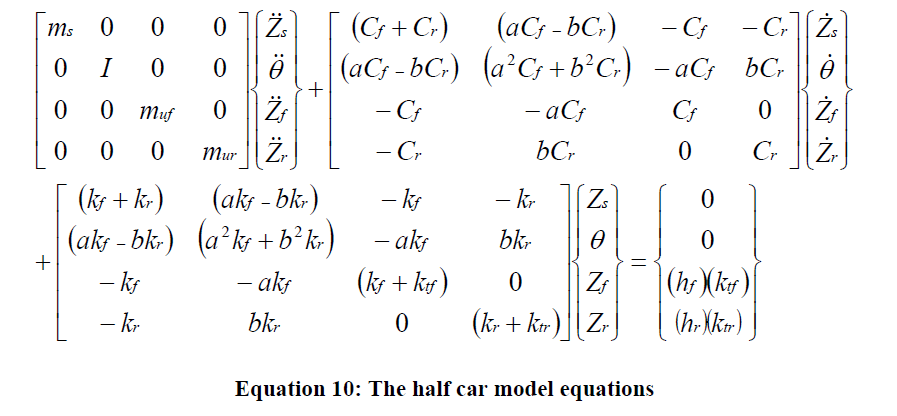

## Mass Matrix

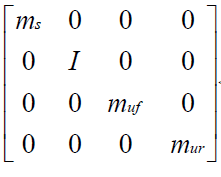

global mass_matrix;
global damping_matrix;
global stiffness_matrix;
    
ms = 1356.65; % Sprung mass (kg)
I = 2100; % Pitch inertia (kg m^2)
muf = 67.835; % Portion of the unsprung mass associated with the front of the vehicle (kg)
mur = 67.835; % Portion of the unsprung mass associated with the rear of the vehicle (kg)

mass_matrix = zeros(4,4);

mass_matrix(1,1) = ms;
mass_matrix(2,2) = I;
mass_matrix(3,3) = muf;
mass_matrix(4,4) = mur;

## `Damping Matrix`

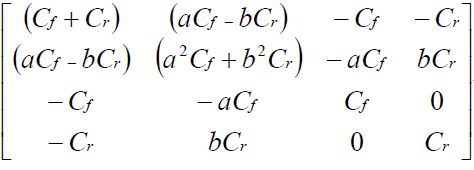

Cf = 2500; % Front damping coefficient (N s/m)
Cr = 2000; % Rear damping coefficient (N s/m)
a = 0.9; % Distance between the center of mass and the front axle (m)
b = 1.2; % Distance between the center of mass and the rear axle (m)

damping_matrix = zeros(4,4);

damping_matrix(1,1) = Cf + Cr;
damping_matrix(1,2) = a*Cf + b*Cr;
damping_matrix(1,3) = -Cf;
damping_matrix(1,4) = -Cr;

damping_matrix(2,1) = a*Cf - b*Cr;
damping_matrix(2,2) = (a^2)*Cf + (b^2)*Cr;
damping_matrix(2,3) = -a*Cf;
damping_matrix(2,4) = b*Cr;

damping_matrix(3,1) = -Cf;
damping_matrix(3,2) = -a*Cf;
damping_matrix(3,3) = Cf;
damping_matrix(3,4) = 0;

damping_matrix(4,1) = -Cr;
damping_matrix(4,2) = b*Cr;
damping_matrix(4,3) = 0;
damping_matrix(4,4) = Cr;


## Stiffness Matrix

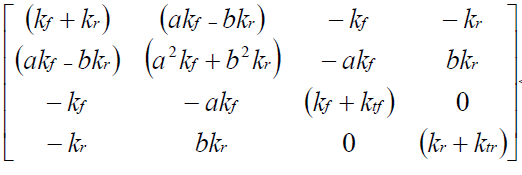

kf = 28000; % Front suspension spring constant (N/m)
kr = 21000; % Rear suspension spring constant (N/m)
global ktr;
global ktf;
ktr = 50000; % Rear tire spring constant (N/m)
ktf = 50000; % Front tire spring constant (N/m)

stiffness_matrix = zeros(4,4);

stiffness_matrix(1,1) = kf + kr;
stiffness_matrix(1,2) = a*kf - b*kr;
stiffness_matrix(1,3) = -kf;
stiffness_matrix(1,4) = -kr;

stiffness_matrix(2,1) = a*kf - b*kr;
stiffness_matrix(2,2) = (a^2)*kf + (b^2)*kr;
stiffness_matrix(2,3) = -a*kf;
stiffness_matrix(2,4) = b*kr;

stiffness_matrix(3,1) = -kf;
stiffness_matrix(3,2) = -a*kf;
stiffness_matrix(3,3) = kf + ktf;
stiffness_matrix(3,4) = 0;

stiffness_matrix(4,1) = -kr;
stiffness_matrix(4,2) = b*kr;
stiffness_matrix(4,3) = 0;
stiffness_matrix(4,4) = kr + ktr;



### Solving

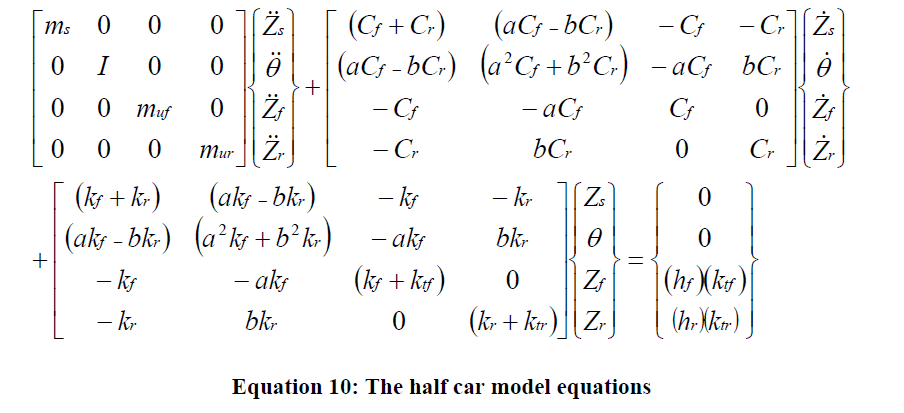

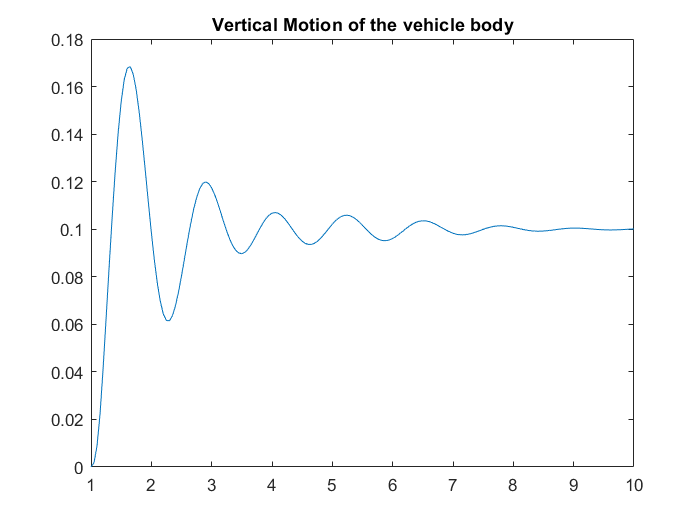

tspan = 1:0.05:10;
size_t = size(tspan);
y0 = zeros(8,1);
[t, x] = ode45(@model, tspan, y0);

figure
plot(tspan, x(:,1))
title('Vertical Motion of the vehicle body')

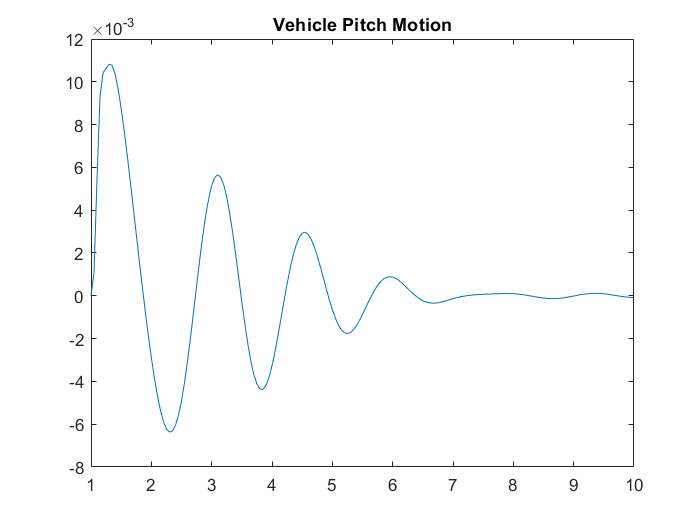


plot(tspan, x(:,2))
title('Vehicle Pitch Motion')

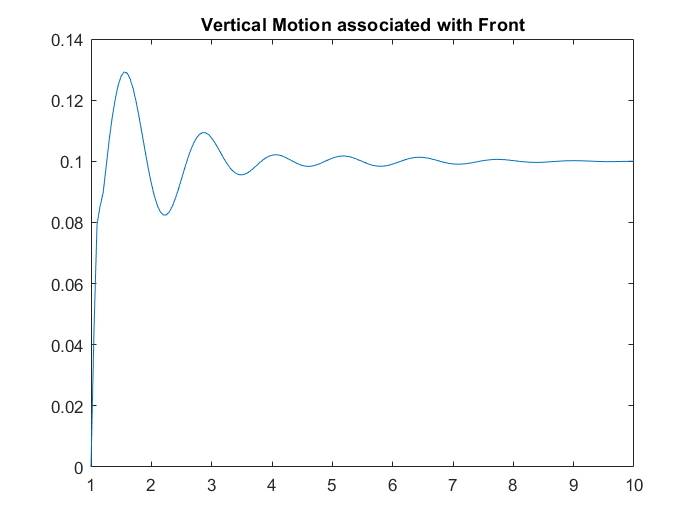


plot(tspan, x(:,3))
title('Vertical Motion associated with Front')

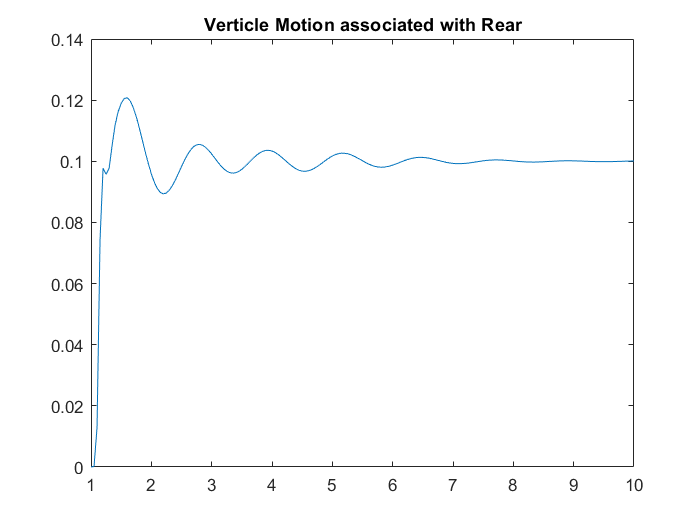


plot(tspan, x(:,4))
title('Verticle Motion associated with Rear')

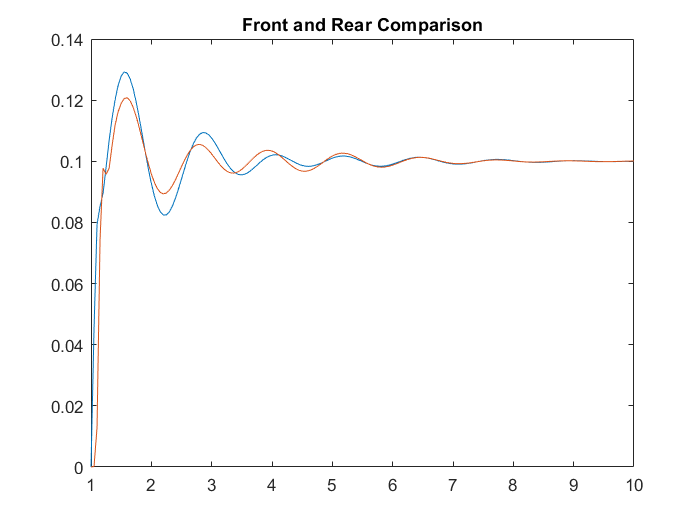


plot(tspan, x(:,3))
title('Front and Rear Comparison')

hold on
plot(tspan, x(:,4))

hold off

% 
% t = tiledlayout(4,1); % Requires R2019b or later
% ax1 = nexttile;
% plot(ax1,tspan,x(:,1))


## Road Disturbance

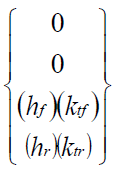

function road_dist = road_disturbance(t)
hf = 0.10; % Disturbance (excitation) motion at the front of the vehicle 
hr = 0.10; % Disturbance (excitation) motion at the rear of the vehicle
global ktf;
global ktr;
road_dist = zeros(4,1);

road_dist(3) = hf*ktf;

wheelbase = 1.5; % Wheelbase in m
speed = 5; % Speed in kmph
speed = speed/3.6; % Speed to mph

timetodist = wheelbase/speed;

if (t<timetodist)
    road_dist(4) = 0;
else
    road_dist(4) = hr*ktr;
end

end


function f = model(t,x)
    global mass_matrix;
    global damping_matrix;
    global stiffness_matrix;
    y = x(1:4);
    y_dot = x(5:8);
    f = zeros(8,1);
    f(1:4) = y_dot;
    f(5:8) = mass_matrix \ (road_disturbance(t) - damping_matrix*y_dot - stiffness_matrix*y);
end